%linear convlution
%circular convolution
%DTMF
%power density spectrum
%sinusoidal generation
%DFT
%IDFT
%FIR - LPF
%    - HPF
%    - BPF
%    - BSF
%    -chebyshev
%    -butterworth
%IIR - LPF
%    - HPF
%    - BPF
%    - BSF
%    - chebyshev
%    - Butterworth
%Interpolation - without function
%              - with function
%Decimation - without function
%           - with function
%CCS
%
%Linear Convolution
%Circular Convolution
%
%


%LINEAR 
clc
 clear all
 close all
 x=input('enter x: ')

x =      1     2     3


 h=input('enter h: ')

h =      4     5     6


 N=length(x)

N = 3

 M=length(h)

M = 3

 l=M+N-1

l = 5

 y=zeros(1,l)

y =      0     0     0     0     0


 for n=1:l
     y(n)=0
     for k=max(1,n-M+1):min(n,N)
         y(n)=y(n)+x(n-k+1)*h(k)
     end
 end

y =      0     0     0     0     0


y =      4     0     0     0     0


y =      4     0     0     0     0


y =      4     8     0     0     0


y =      4    13     0     0     0


y =      4    13     0     0     0


y =      4    13    12     0     0


y =      4    13    22     0     0


y =      4    13    28     0     0


y =      4    13    28     0     0


y =      4    13    28    15     0


y =      4    13    28    27     0


y =      4    13    28    27     0


y =      4    13    28    27    18


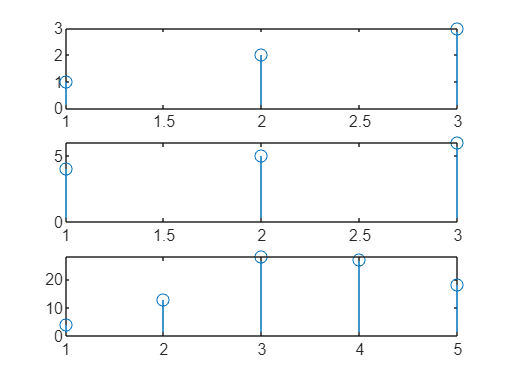

 subplot(3,1,1)
 stem(x)
 subplot(3,1,2)
 stem(h)
 subplot(3,1,3)
 stem(y)

clc
clear all
close all
x=input('enter x: ')

x =      1     2     3     4


h=input('enter h: ')

h =      2     1     2     1


N=length(x)

N = 4

M=length(h)

M = 4

l=N+M-1

l = 7

y=zeros(1,l)

y =      0     0     0     0     0     0     0


for n=1:l
    for k=max(1,n-M+1):min(n,N)
        y(n)=y(n)+x(n-k+1)*h(k)
    end
end

y =      2     0     0     0     0     0     0


y =      2     4     0     0     0     0     0


y =      2     5     0     0     0     0     0


y =      2     5     6     0     0     0     0


y =      2     5     8     0     0     0     0


y =      2     5    10     0     0     0     0


y =      2     5    10     8     0     0     0


y =      2     5    10    11     0     0     0


y =      2     5    10    15     0     0     0


y =      2     5    10    16     0     0     0


y =      2     5    10    16     4     0     0


y =      2     5    10    16    10     0     0


y =      2     5    10    16    12     0     0


y =      2     5    10    16    12     8     0


y =      2     5    10    16    12    11     0


y =      2     5    10    16    12    11     4


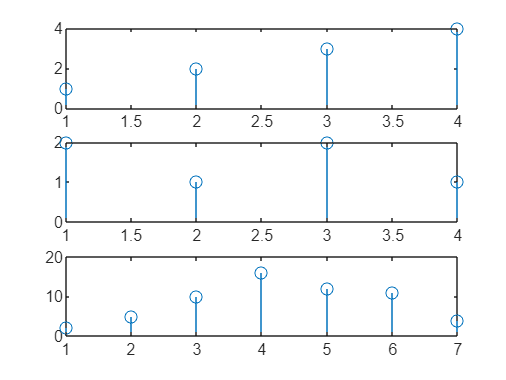

subplot(3,1,1)
stem(x)
subplot(3,1,2)
stem(h)
subplot(3,1,3)
stem(y)

clc
clear all
close all
x=input('enter x: ')

x =      1     2     3     4


h=input('enter h: ')

h =      2     1     2     1


N=max(length(x),length(h))

N = 4

y=zeros(1,N)

y =      0     0     0     0


for n=1:N
    y(n)=0
    for k=1:N
        id=mod(n-k,N)+1
        y(n)=y(n)+x(id)*h(k)
    end
end

y =      0     0     0     0


id = 1

y =      2     0     0     0


id = 4

y =      6     0     0     0


id = 3

y =     12     0     0     0


id = 2

y =     14     0     0     0


y =     14     0     0     0


id = 2

y =     14     4     0     0


id = 1

y =     14     5     0     0


id = 4

y =     14    13     0     0


id = 3

y =     14    16     0     0


y =     14    16     0     0


id = 3

y =     14    16     6     0


id = 2

y =     14    16     8     0


id = 1

y =     14    16    10     0


id = 4

y =     14    16    14     0


y =     14    16    14     0


id = 4

y =     14    16    14     8


id = 3

y =     14    16    14    11


id = 2

y =     14    16    14    15


id = 1

y =     14    16    14    16


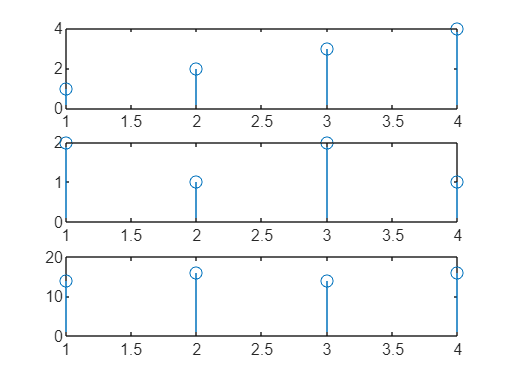

subplot(3,1,1)
stem(x)
subplot(3,1,2)
stem(h)
subplot(3,1,3)
stem(y)

clc
clear all
close all
dtmf_fq=[
    941,1336;%0
    697,1209;%1
    697,1336;%2
    770,1209;%3
    770,1336;%4
    770,1477;%5
    852,1209;%6
    852,1336;%7
    852,1477;%8
    941,1336;%9
    ]

dtmf_fq =          941        1336
         697        1209
         697        1336
         770        1209
         770        1336
         770        1477
         852        1209
         852        1336
         852        1477
         941        1336


digit=input('enter digit: ')

digit = 2

duration = 0.5000

fs = 44100

t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


tone1 =          0    0.0991    0.1973    0.2935    0.3869    0.4764    0.5612    0.6405    0.7135    0.7794    0.8377    0.8877    0.9290    0.9611    0.9838    0.9967    0.9998    0.9931    0.9766    0.9505    0.9150    0.8705    0.8174    0.7562    0.6877    0.6123    0.5309    0.4443    0.3532    0.2588    0.1617    0.0631   -0.0362   -0.1351   -0.2326   -0.3279   -0.4200   -0.5079   -0.5908   -0.6679   -0.7384   -0.8016   -0.8569   -0.9038   -0.9418   -0.9705   -0.9896   -0.9990   -0.9985   -0.9882


tone2 =          0    0.1892    0.3716    0.5405    0.6899    0.8144    0.9095    0.9717    0.9988    0.9899    0.9452    0.8663    0.7562    0.6187    0.4589    0.2825    0.0959   -0.0942   -0.2808   -0.4574   -0.6173   -0.7550   -0.8655   -0.9446   -0.9896   -0.9989   -0.9721   -0.9102   -0.8154   -0.6912   -0.5419   -0.3732   -0.1909   -0.0017    0.1875    0.3700    0.5391    0.6887    0.8134    0.9088    0.9713    0.9988    0.9901    0.9457    0.8672    0.7573    0.6200    0.4604    0.2841    0.0976


tone =          0    0.2883    0.5689    0.8340    1.0768    1.2908    1.4707    1.6122    1.7123    1.7693    1.7829    1.7540    1.6851    1.5798    1.4426    1.2792    1.0957    0.8989    0.6958    0.4931    0.2976    0.1154   -0.0481   -0.1884   -0.3020   -0.3866   -0.4412   -0.4660   -0.4622   -0.4324   -0.3802   -0.3101   -0.2271   -0.1368   -0.0451    0.0421    0.1191    0.1808    0.2227    0.2409    0.2330    0.1972    0.1332    0.0419   -0.0746   -0.2132   -0.3696   -0.5386   -0.7144   -0.8906


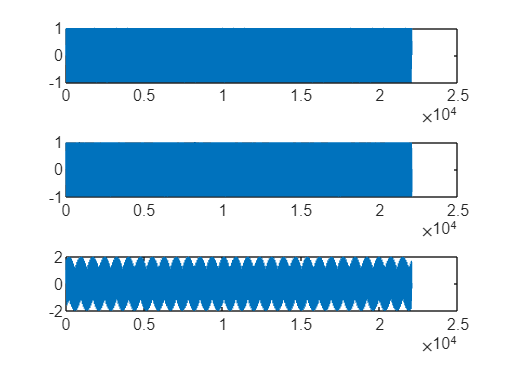

if digit>=0 && digit<=9
    duration=0.5
    fs=44100
    t=0:1/fs:duration
    tone1=sin(2*pi*dtmf_fq(digit+1,1)*t)
    tone2=sin(2*pi*dtmf_fq(digit+1,2)*t)
    tone=tone1+tone2
    sound(tone)
    subplot(3,1,1)
    plot(tone1)
    subplot(3,1,2)
    plot(tone2)
    subplot(3,1,3)
    plot(tone)
else
    disp("invalid")
end

clc
clear all
close all
f1=500

f1 = 500

f2=2000

f2 = 2000

fs=8000

fs = 8000

N=200

N = 200

t=0:N-1

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=2*sin(2*pi*f1*t)+3*sin(2*pi*f2*t)

x = 1.0e-08 *

         0   -0.0004   -0.0009   -0.0007   -0.0018   -0.0029   -0.0014   -0.0025   -0.0036   -0.0047   -0.0058   -0.0069   -0.0029   -0.0090   -0.0050   -0.0112   -0.0072   -0.0032   -0.0094   -0.0054   -0.0115   -0.0075   -0.0137   -0.0199   -0.0057   -0.0119   -0.0181   -0.0039   -0.0101   -0.0162   -0.0224   -0.0082   -0.0144   -0.0206   -0.0064   -0.0126   -0.0187   -0.0249   -0.0107   -0.0169   -0.0231   -0.0089   -0.0151   -0.0213   -0.0274   -0.0336   -0.0398   -0.0052   -0.0114   -0.0176


y=2*abs(fft(x))/N

y = 1.0e-09 *

    0.8892    0.2938    0.1582    0.0988    0.0768    0.0506    0.0319    0.0305    0.0446    0.0756    0.0691    0.0862    0.0850    0.1258    0.0560    0.1045    0.0548    0.0556    0.0378    0.0147    0.0237    0.0113    0.0379    0.0126    0.0324    0.0183    0.0433    0.0585    0.0554    0.0712    0.0230    0.0286    0.0192    0.0086    0.0011    0.0165    0.0077    0.0271    0.0223    0.0285    0.0228    0.0453    0.0222    0.0302    0.0142    0.0172    0.0228    0.0080    0.0089    0.0140


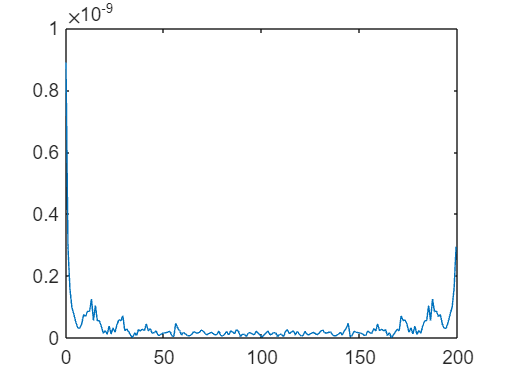

plot(t,y)

clc
clear all
close all
fc=100

fc = 100

fs=1000

fs = 1000

f=50

f = 50

t=0:1/fs:1-1/fs

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


x=2*sin(2*pi*f*t)+randn(size(t))

x =     0.2962    1.8188    2.2657    1.2593    1.7722    2.7337    2.0224    2.7544    0.4888    1.0897    0.2883    0.7738   -2.5211   -1.6173   -1.8486   -4.3419   -0.6540    1.1912   -1.4078   -0.3310   -0.4646    1.0024    0.7957    1.5163    3.5203    1.1528    1.3262    1.5421    1.0431    2.0573    2.0313   -1.5962   -1.8166   -1.0976   -2.2828   -0.0071   -0.2662   -1.0590   -0.6119   -0.9564    0.7636    1.7455    1.3171    3.5462    2.5728    1.8899    2.2731    2.7146    0.7774    0.5326


order=4

order = 4

[b,a]=butter(order,fc/(fs/2),"low")

b =     0.0048    0.0193    0.0289    0.0193    0.0048


a =     1.0000   -2.3695    2.3140   -1.0547    0.1874


y=filter(b,a,x)

y =     0.0014    0.0179    0.0937    0.2902    0.6245    1.0400    1.4567    1.8212    2.0997    2.2491    2.2179    1.9878    1.5909    1.0645    0.4251   -0.2990   -1.0513   -1.7264   -2.1484   -2.1765   -1.8391   -1.2989   -0.7185   -0.1874    0.2795    0.7191    1.1579    1.5511    1.8145    1.9025    1.8441    1.7089    1.5125    1.1805    0.6483   -0.0392   -0.7288   -1.2335   -1.4414   -1.3747   -1.1405   -0.8319   -0.4712   -0.0335    0.5036    1.1250    1.7500    2.2593    2.5668    2.6382


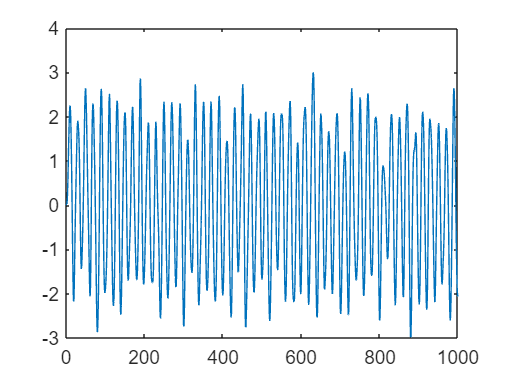

plot(y)

clc
clear all
close all
x=input('enter x')

x =      1     2     3     4


N=length(x)

N = 4

y=zeros(N,1)

y =      0
     0
     0
     0


for k=0:N-1
    for n=0:N-1
        y(k+1)=y(k+1)+x(n+1)*exp(-1*1i*2*pi*n*k/N)
    end
end

y =      1
     0
     0
     0


y =      3
     0
     0
     0


y =      6
     0
     0
     0


y =     10
     0
     0
     0


y =     10
     1
     0
     0


y =   10.0000 + 0.0000i
   1.0000 - 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 - 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   1.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -1.0000 - 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
   2.0000 + 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   0.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   1.0000 + 0.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
   1.0000 + 2.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
  -2.0000 + 2.0000i


y =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
  -2.0000 - 2.0000i


clc
clear all
close all
x=input('enter x')

x =      1     2     3     4


N=length(x)

N = 4

y=zeros(N,1)

y =      0
     0
     0
     0


for k=0:N-1
    for n=0:N-1
        y(k+1)=y(k+1)+x(n+1)*exp(1*1i*2*pi*n*k/N)
    end
    y(k+1)=y(k+1)/N
end

y =      1
     0
     0
     0


y =      3
     0
     0
     0


y =      6
     0
     0
     0


y =     10
     0
     0
     0


y =     2.5000
         0
         0
         0


y =     2.5000
    1.0000
         0
         0


y =    2.5000 + 0.0000i
   1.0000 + 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -2.0000 + 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -2.0000 - 2.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
   1.0000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -1.0000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
   2.0000 - 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -2.0000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
   0.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
   1.0000 + 0.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
   1.0000 - 2.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
  -2.0000 - 2.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
  -2.0000 + 2.0000i


y =    2.5000 + 0.0000i
  -0.5000 - 0.5000i
  -0.5000 + 0.0000i
  -0.5000 + 0.5000i


%IIR LPF
clc
clear all
close all
fc=100

fc = 100

fs=1000

fs = 1000

order=4

order = 4

f=50

f = 50

t=0:1/fs:1-1/fs

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))

sgnl =     0.4353    0.7834    0.5016    2.3920    1.5938    1.6507    1.1903    1.5632    1.1242    0.4567   -0.4198   -1.4483    0.3307   -0.8676   -2.0816   -2.0574   -1.7227   -1.6241   -1.4608   -0.1510   -0.5692    1.5967    0.2940    1.4564    2.3384    2.0590    1.1506    2.0790    1.2572    0.2107    0.2019   -0.2400   -0.0834   -1.6649   -2.0492   -2.2524   -2.8656   -1.3573   -2.2028   -0.7530   -0.1375    1.0406   -0.2100    2.0771    1.6425    1.3535    1.8978    1.7347    0.9635   -0.1167


subplot(2,1,1)
plot(sgnl)
[b,a]=butter(order,fc/(fs/2),"low")

b =     0.0048    0.0193    0.0289    0.0193    0.0048


a =     1.0000   -2.3695    2.3140   -1.0547    0.1874


freqz(b,a,2400,'half',44100)
filsgnl=filter(b,a,sgnl)

filsgnl =     0.0021    0.0172    0.0659    0.1710    0.3560    0.6355    0.9824    1.3213    1.5706    1.6813    1.6341    1.4178    1.0329    0.5294    0.0062   -0.4624   -0.8687   -1.2259   -1.5217   -1.7174   -1.7660   -1.6294   -1.2947   -0.7910   -0.1898    0.4309    1.0111    1.4908    1.8133    1.9501    1.8949    1.6535    1.2613    0.7837    0.2792   -0.2329   -0.7568   -1.2814   -1.7561   -2.1021   -2.2459   -2.1381   -1.7671   -1.1847   -0.4909    0.2144    0.8476    1.3423    1.6646    1.8032


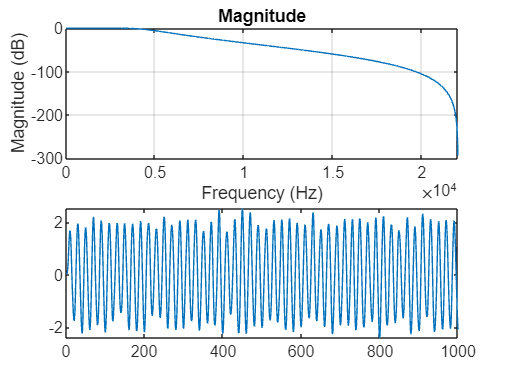

subplot(2,1,2)
plot(filsgnl)

%IIR LPF
clc
clear all
close all
fc=100

fc = 100

fs=1000

fs = 1000

order=4

order = 4

f=50

f = 50

t=0:1/fs:1-1/fs

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))

sgnl =     0.6528    1.1100    0.5499    1.5282    1.5304    2.1166    2.9528    1.1797    2.1500    0.3854   -0.3260   -0.3132   -0.8210   -1.4781   -2.6358   -2.3457   -2.3361   -1.8743   -1.5666   -0.4051    0.5058    0.4927    1.4527    1.9975    1.9690    1.8637    1.6308    1.0365    1.0388    0.6978   -0.0934   -0.5091   -1.1525   -1.2829   -2.2174   -2.0592   -1.7811   -1.8061   -1.0353   -1.5053    0.2293    0.8489    1.1750    1.4416    1.6856    1.1476    2.4500    1.9359    0.6320   -0.1206


subplot(2,1,1)
plot(sgnl)
[b,a]=butter(order,fc/(fs/2),"high")

b =     0.4328   -1.7314    2.5971   -1.7314    0.4328


a =     1.0000   -2.3695    2.3140   -1.0547    0.1874


freqz(b,a,2400,'half',44100)
filsgnl=filter(b,a,sgnl)

filsgnl =     0.2826    0.0197   -0.5955    0.3032   -0.1304    0.1214    0.2009   -1.0923    0.6539   -0.4220    0.3082    0.8190    0.2635   -0.1671   -0.5125    0.2922    0.0611    0.0249   -0.2580    0.0396   -0.2087   -0.6764    0.0830    0.1122   -0.0680    0.0769    0.2055    0.1369    0.4587    0.1509   -0.2374   -0.0500   -0.1143    0.1478   -0.2842    0.2645    0.2196   -0.1812    0.0535   -0.6291    0.5261   -0.1354   -0.4194   -0.2619    0.0232   -0.1007    0.9739   -0.1037   -0.5826    0.0416


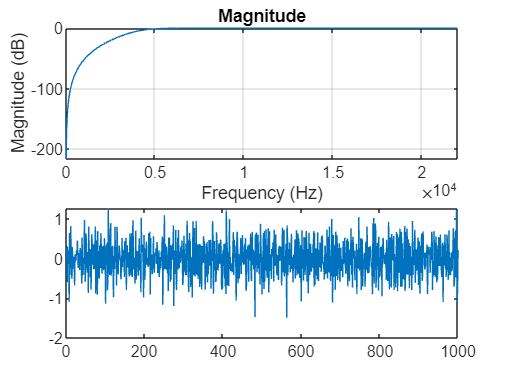

subplot(2,1,2)
plot(filsgnl)

clc
clear all
close all
lf=0.2

lf = 0.2000

hf=0.4

hf = 0.4000

order=4

order = 4

f=50

f = 50

fs=1000

fs = 1000

t=0:1/fs:1-1/fs

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))

sgnl =    -0.3227    0.4735    1.6758    1.3240    2.6809    1.3193    2.8522    1.7070    0.0923    0.9715   -1.1127   -0.4474   -0.0500   -1.7011   -1.6586   -1.6635   -2.0896   -1.2078   -1.3630   -0.1788   -0.4990    0.6533    1.0303    1.2289    1.9464    1.2632    1.0822    0.8914    0.7739    1.0393    0.0249    0.0059   -0.6820   -1.8586   -2.5825   -1.9861   -2.0760   -1.0060   -1.5424    0.1717    0.1271    0.8502    0.8181    1.1101    1.8141    2.0106    1.1717    1.6733    0.7912    0.8287


subplot(2,1,1)
plot(sgnl)
[b,a]=butter(order,[lf,hf],"bandpass")

b =     0.0048         0   -0.0193         0    0.0289         0   -0.0193         0    0.0048


a =     1.0000   -3.9366    8.2604  -11.2174   10.7836   -7.3914    3.5765   -1.1150    0.1874


freqz(b,a,2400,'half',44100)
filsgnl=filter(b,a,sgnl)

filsgnl =    -0.0016   -0.0038    0.0120    0.0589    0.0775   -0.0223   -0.2027   -0.2669   -0.0848    0.2010    0.3362    0.2570    0.0977   -0.0259   -0.1505   -0.3298   -0.4208   -0.2097    0.2374    0.5491    0.4346    0.0009   -0.3636   -0.3847   -0.1411    0.0850    0.1267    0.0549    0.0384    0.1332    0.2127    0.1105   -0.1609   -0.3744   -0.3215   -0.0316    0.2883    0.4387    0.3206   -0.0255   -0.3910   -0.5064   -0.2855    0.0792    0.3232    0.3570    0.2543    0.0787   -0.1371   -0.2933


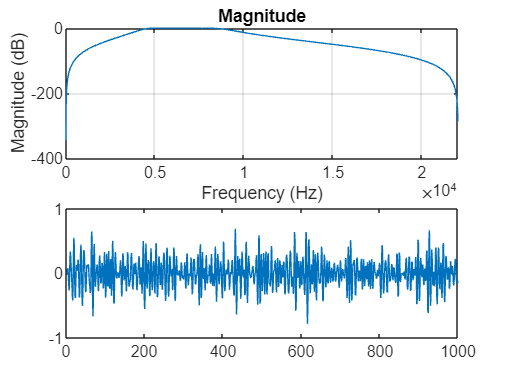

subplot(2,1,2)
plot(filsgnl)

clc
clear all
close all
lf=0.2

lf = 0.2000

hf=0.4

hf = 0.4000

order=4

order = 4

f=50

f = 50

fs=1000

fs = 1000

t=0:1/fs:1-1/fs

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))

sgnl =    -0.5250    0.8524    1.3170    2.2886    2.0924    2.7177    2.3019    2.4323    1.2401   -0.4243   -0.3236   -0.7439   -1.0805   -1.8518   -1.6367   -1.8777   -0.9289   -2.2566   -1.1718   -0.7998    0.6334    0.8871    1.5790    1.5623    2.3586    2.7623    1.5559    1.1668    1.2108    0.2738    0.6155   -0.7553   -1.7274   -1.5774   -2.2950   -2.7318   -1.7037   -1.9002   -0.9865   -0.0328   -0.0229    0.3005    1.3413    2.0591    2.1114    1.9797    1.8670    1.1107    1.1087    0.5976


subplot(2,1,1)
plot(sgnl)
[b,a]=butter(order,[lf,hf],"stop")

b =     0.4328   -2.1401    5.6994   -9.6901   11.5435   -9.6901    5.6994   -2.1401    0.4328


a =     1.0000   -3.9366    8.2604  -11.2174   10.7836   -7.3914    3.5765   -1.1150    0.1874


freqz(b,a,2400,'half',44100)
filsgnl=filter(b,a,sgnl)

filsgnl =    -0.2273    0.5980   -0.0153    0.5688    0.7174    1.7331    1.5537    2.1875    1.9966    2.0787    2.4562    0.9930    0.1643   -0.4745   -0.6596   -1.8717   -1.9454   -2.9350   -1.2473   -1.5621   -1.0137   -0.9826    0.2341    0.6232    1.3266    1.3762    1.2907    2.4327    2.4993    1.4446    1.7408    0.6503    0.4552    0.0124   -1.5937   -1.9828   -1.5475   -2.4962   -2.0049   -1.8278   -1.7712   -0.7867    0.1157    0.3207    0.7480    1.6252    2.1601    1.8770    2.0914    1.6054


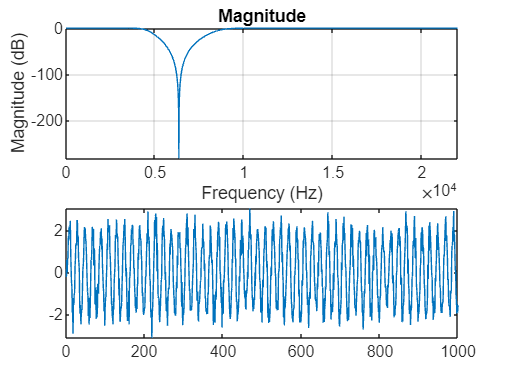

subplot(2,1,2)
plot(filsgnl)

clc
clear all
close all
f=50
fc=100
fs=1000
t=0:1/fs:1-1/fs
sgnl=2*sin(2*pi*f*t)+0.5*randn(size(t))
coeff=fir1(order,fc,'low')
